# Discretizing Landscape Evolution

Gwen Diamond, Grace Hansen

## **Introduction**

Landscape evolution, particularly through evolution and deposition of sediment, is studied on multiple levels and for many reasons. The creation of digital elevation models (DEMs) initiated many of these studies because these models were a canvas on which processes such as hydrology and erosion could be illustrated numerically. This opened the door for landscape evolution models (LEMs), which employ DEMs to incorporate landscape evolution processes due to rainfall, the formation of rivers and river channels, and tectonic uplift. Aside from the overall interest in watching a decades-long process play out numerically, landscape evolution is important for other reasons. For instance, validating the models of landscape evolution is also validating the processes which are represented in the model. This can either confirm or bring into question the processes which were assumed to determine the landscape.  Furthermore, Willgoose (2005) presents the application of landscape evolution to agricultural erosion models in order to prevent unexpected amounts of erosion leading to a failure to contain agricultural waste. Willgoose (2005) suggests the importance of landscape evolution in containing radioactive waste as well. If the goal is to successfully bury radioactive materials, it is necessary to make sure that those materials remain buried rather than the layers of soil above it eroding away. Other applications include slope stability, erosion prevention, soil recovery, and even paleo-climate studies of deposition materials.

Most models of landscape evolution include a space parameter in addition to the parameters used below. In this way, a hill or some landscape is shown in three dimensions, as well as time. Graph representations appear as the landscape would appear to the human eye over time. As a simplification, the model below uses a transect of a mountain slope and its evolution over time. Other papers consider hillslope evolution in terms of catchments, where rivers meet to form another river (Willgoose 1994). Caviedes-Voullième et al. (2021) shows how such flow from rainfall runoff interacts with land and gravity to either pool or form a channel-flow. This study is more recent than those by Willgoose, so it is able to go beyond the computing and numeric limits to illustrate flow in more directions than most models which Willgoose discusses. This paper shows the importance of knowing the flow direction in order to use the proper discretization methods to maintain model stability.

## **Equations**

Transport of sediment is described by Willgoose (2004) in the following equation:


$$\frac{\delta z}{\delta t}=U+\Sigma_i \bigtriangledown *Q_{\textrm{si}}$$


z refers to the elevation, and elevation increases with U, the rate of tectonic uplift. This is treated as a source of mass in this equation. A positive del*Q_si describes the deposition rate and a negative del*Q_si describes erosion. Willgoose (2004) visualizes the sediment transport in the form of nodes, or points in space and time. Sediment enters or leaves a node with the capacity to be transported or deposited. For instance, if sediment enters a node with more transport potential than it has leaving the node, the sediment is deposited. In this case, the sediment flow is deposition-limited. On the other hand, if the transport potential of a sediment leaving a node is larger than transport potential entering, erosion occurs. Erosion is limited by the surface which is being eroded and its exposure to erosion. This becomes a detachment-limited process because there are limits on detachment, or erosion. 

The transport rate is related to the grading of the material being eroded and deposited, which can vary. Transport rate is also determined by hydrological processes, so the change in elevation must be determined by multiple values of del*Q_si. Q_si is dependent on the rate of detachment, mass per detachment, and distance traveled. If the distance traveled is infinity, the sediment is not limited by transport and is instead limited only by its ability to be eroded, so it is detachment-limited. There is debate as to whether a river process may be detachment- or transport-limited, but Willgoose (2004) concludes that upstream reaches are detachment-limited. As the DEM employed below is from a mountain slope in the Rocky Mountains, the model assumes that the flow is detachment limited, so the equation for elevation can be simplified to:

 
$$\frac{\mathrm{dz}}{\mathrm{dt}}=U-D$$


We planned to assume varying amounts of tectonic movement, but we first decided to begin with no tectonic movement and just focus on the transport of soil in one direction.

 The diffusion equation used later in the paper is 


$$\frac{\delta z}{\delta t}=\kappa *\nabla^2 *z$$
 

(Pelletier 2013). 

This is equivalent to 

$\frac{\delta z}{\delta t}=D*\frac{\delta^2 z}{\delta x^2 }$, where D= 𝜿 (diffusivity).  

## **Numerical Methods**

When applying this to a one-dimensional mountain transect, this can resemble a hillslope diffusion problem. Considering the transport of sediment in flowing water, however, this can resemble an advection problem. The models below employ the methods for both of these types of problems in an attempt to emulate the expected erosion and the models in other papers.

To represent advection on the mountain slope, the Forward Euler upwind scheme was applied to the transect. In order to maintain the stability of the method, a transect was specifically chosen such that the flow is in one direction. Using a method such as centered differencing would have resulted in artificial diffusion as well as advection, so the Forward Euler upwind scheme was used and its requirements were attempted to be met. Considering the original assumption to begin with no tectonic uplift or additional mass being added to the system, there is a no-flux Neumann boundary condition at $x=0$ meters.

To see if diffusion is a better representation of erosion on the mountain transect, diffusion is also applied. The diffusion was discretized using both Forward Euler ($\theta =0$), Backward Euler, and Crank-Nicholson ($\theta =0\ldotp 5$). Backward Euler is unconditionally stable, but Crank-Nicholson is more accurate than Backward Euler as well as unconditionally stable. For Forward Euler to be stable, $C_D$ had to be less than or equal to 0.5, so the size of the time steps is chosen specifically to maintain stability. Backward Euler and Crank-Nicholson both require inverting the matrix version of the equations. This is normally a costly computation, but this step only needs to be performed once since the matrix does not change, and it is tridiagonal, meaning there are more efficient numerical methods to invert it.

Then, because there was no longer a requirement to keep the slope in one direction, the diffusion methods (Forward Euler, Backward Euler, and Crank-Nicholson) were applied to a transect where there was a peak in the middle rather than at $x=0$ meters. For all diffusion problems, a no-flux boundary condition was applied at both ends of the spatial domain.

## **Results**

clear; clc; close all
lat=40.025;

slope1.mat contains elevation and longitude data taken for a mountain profile from SRTM 1 Arc-Second Global (retrieved on earthexplorer.usgs.com).

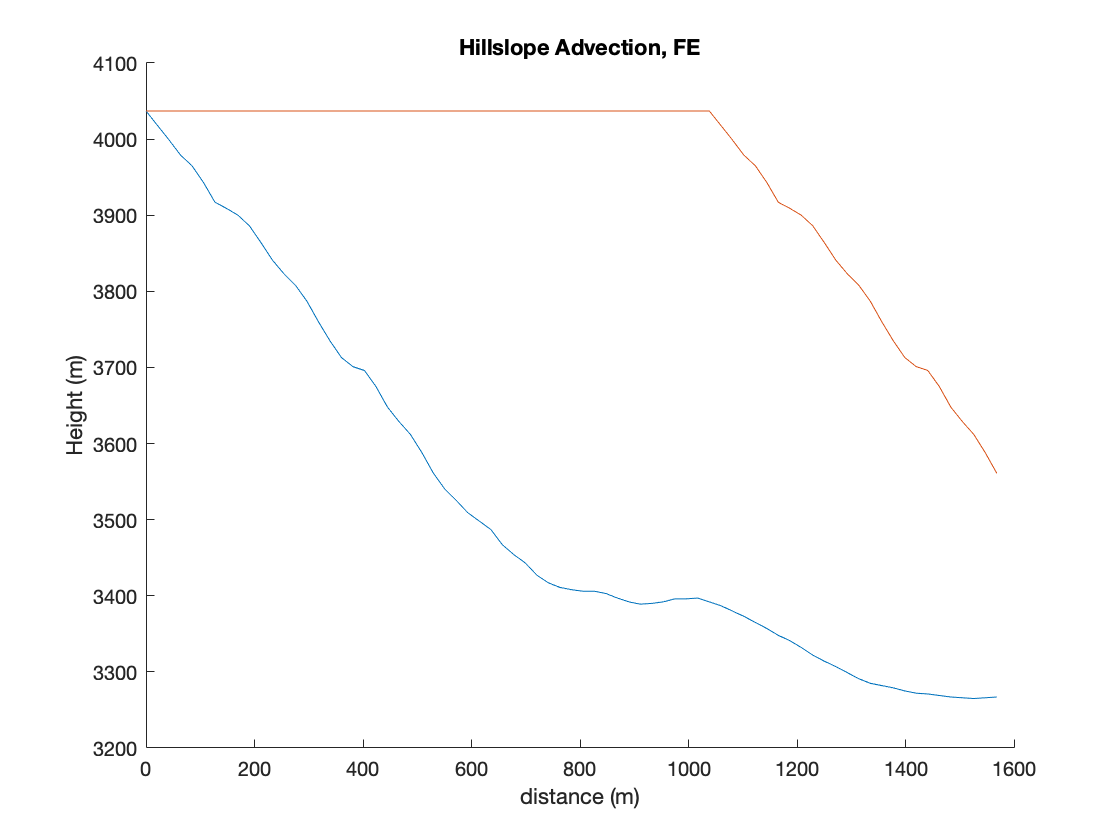

% Basic Advection
load slope1.mat; 
X=(X-X(end))*40075*(10^3)*cos(lat)/360; %m 
X= fliplr(X); 
Z= fliplr(Z);

dx=X(2);
C=1;
u=.0005; %m/years
dt=C*dx/u;
m=length(X); 

n=1000; %timesteps
tf=n*dt;

Zik=nan.*ones(length(Z),n);
Zik(:,1)=Z; 

M=sparse(m,m);
for i = 1:m
    for j = 1:m
        if i==j
            M(i,j) = 1-C;
        elseif i-1==j
            M(i,j) = C;
        end
    end
end
M(1,1)=1;


Z=Zik(:,1);
for i=1:(n); 
    Znew=M*Z;
    Zik(:,i+1)=Znew;
    Z=Znew;
end

figure(1)
hold on
plot(X,Zik(:,1))
plot(X,Zik(:,50))
title('Hillslope Advection, FE')
xlabel('distance (m)')
ylabel('Height (m)')

Applying the Forward Euler upwind scheme to a down-sloping transect so that the advection would occur in one direction was in reality an oversimplification of the process. It was assumed that the sediment could flow in the positive x-direction using a slope that goes downwards in the positive x direction. 

In reality, this overlooks the fact that the gradient of the slope is not constant even if its sign is. Plus, the sediment must move along this more complicated slope in both the x and y dimensions, not simply in the positive x direction. Because this could not be successfully accounted for, the mountain appears to simply shift over time. This brings into question the model's conservation of mass, or rather its creation of mass where there was not intended to be. The “Hillslope Advection, FE” figure shows this shortcoming. The blue line indicates the original mountain transect, and the red line shows it after 50 time steps have passed. This issue may be credited to trouble implementing the spatial divergence operator, $\nabla \bullet$. Pelletier (2013) was referenced for guidance, but this considers the model with the 3rd spatial dimension and so is focused on 3-dimensional flow rather than the two dimensions here. The results in this figure do not fit results in other papers, even when taking into account that most other models have the additional space dimension. 

% Advection-Diffusion
load slope1.mat; 
X=(X-X(end))*40075*(10^3)*cos(lat)/360; %m 
X= fliplr(X);
Z= fliplr(Z);

dx=X(2);
C=.1;
Cd=.5

Cd = 0.5000

u=.0005; %m/years
dt=C*dx/u;
m=length(X);

n=1000; %timesteps
tf=n*dt;

Zik=nan.*ones(length(Z),n);
Zik(:,1)=Z; 

M=sparse(m,m)

M =    All zero sparse: 75×75


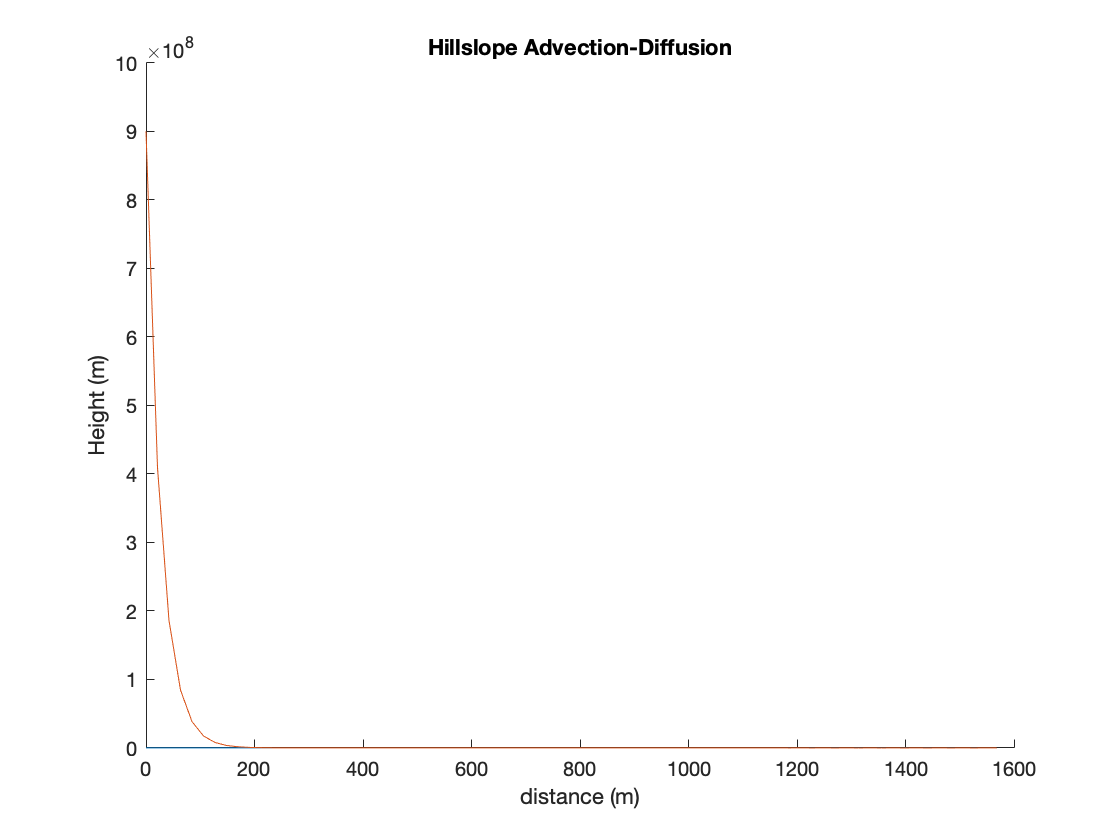

for i = 1:m
    for j = 1:m
        if i==j
            M(i,j) = 1-2*Cd-C;
        elseif i-1==j
            M(i,j) = Cd;
        elseif i+1==j
            M(i,j) = C+Cd;
        end
    end
end
M(1,1)=1;

Z=Zik(:,1);
for i=1:(n); 
    Znew=M*Z;
    Zik(:,i+1)=Znew;
    Z=Znew;
end

figure(2)
hold on
plot(X,Zik(:,1))
plot(X,Zik(:,50))
title('Hillslope Advection-Diffusion')
xlabel('distance (m)')
ylabel('Height (m)')

Since there may be both advection and diffusion happening, this possibility was tested out but met with less success.

The next attempt includes solely diffusion, and its results are more reasonable.

% Hillsope Diffusion
%Convert X from longitude to meters

load slope1.mat; 
X=(X-X(end))*40075*(10^3)*cos(lat)/360; %m 
X= fliplr(X);
Z= fliplr(Z);

m=length(Z)

m = 75

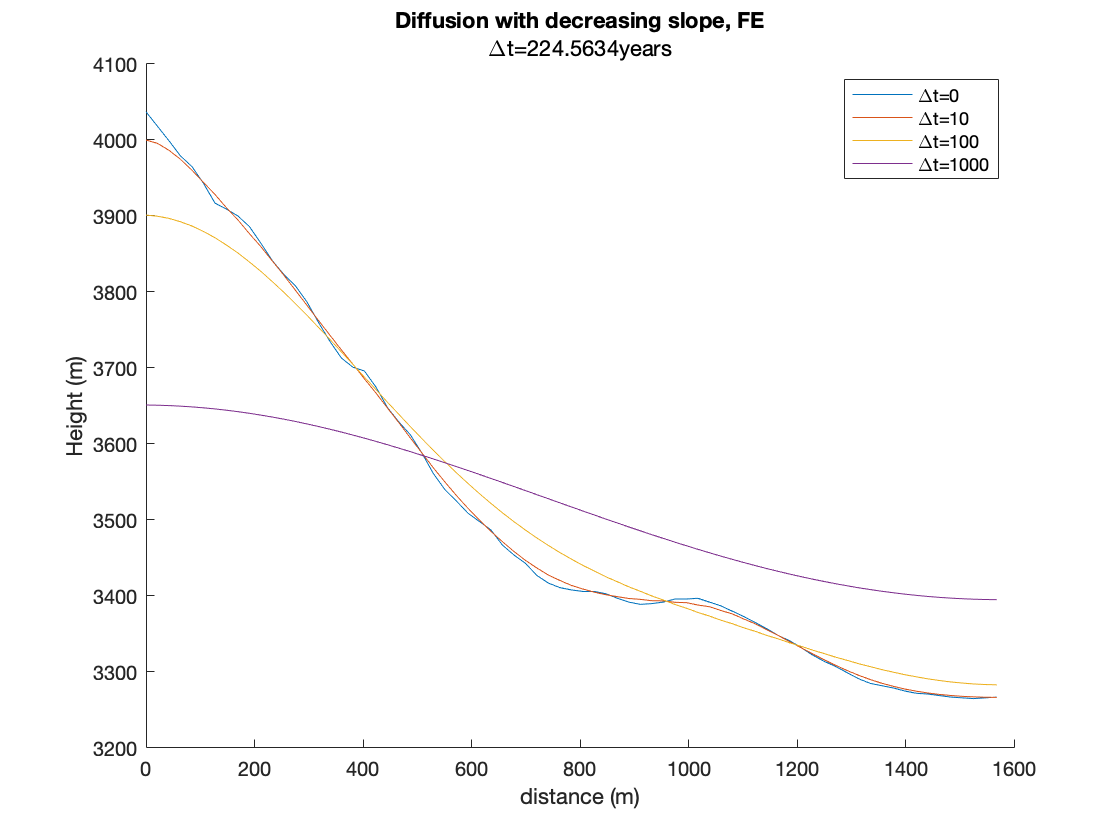

Cd=.5;
dx=X(2);
D=1; % m/yr;
dt=Cd*dx^2/D;

n=1000;

Zik=nan.*ones(length(Z),n);
Zik(:,1)=Z; 


M = sparse(m,m);
for i = 1:m
    for j = 1:m
        if i==j
            M(i,j) = 1-2*Cd;
        elseif i-1==j
            M(i,j) = Cd;
        elseif i+1==j
            M(i,j) = Cd;
        end
    end
end
M(1,1)=1-Cd;
M(end,end)=1-Cd;

Z=Zik(:,1);
for i=1:(n); 
    Znew=M*Z;
    Zik(:,i+1)=Znew;
    Z=Znew;
end

figure(3)
hold on
plot(X,Zik(:,1))
plot(X,Zik(:,10))
plot(X,Zik(:,100))
plot(X,Zik(:,1000))
legend('\Deltat=0','\Deltat=10','\Deltat=100','\Deltat=1000')
title('Diffusion with decreasing slope, FE')
subtitle(['\Deltat=',num2str(dt),'years'])
xlabel('distance (m)')
ylabel('Height (m)')

The results of this run are clearly faulty. The Diffusion occurs on both sides of the profile, which we assumed would only happen on the right. The results do look similar to the hillslope model we made in class, so it seems like a profile with a peak in the middle would be better for using diffusion.

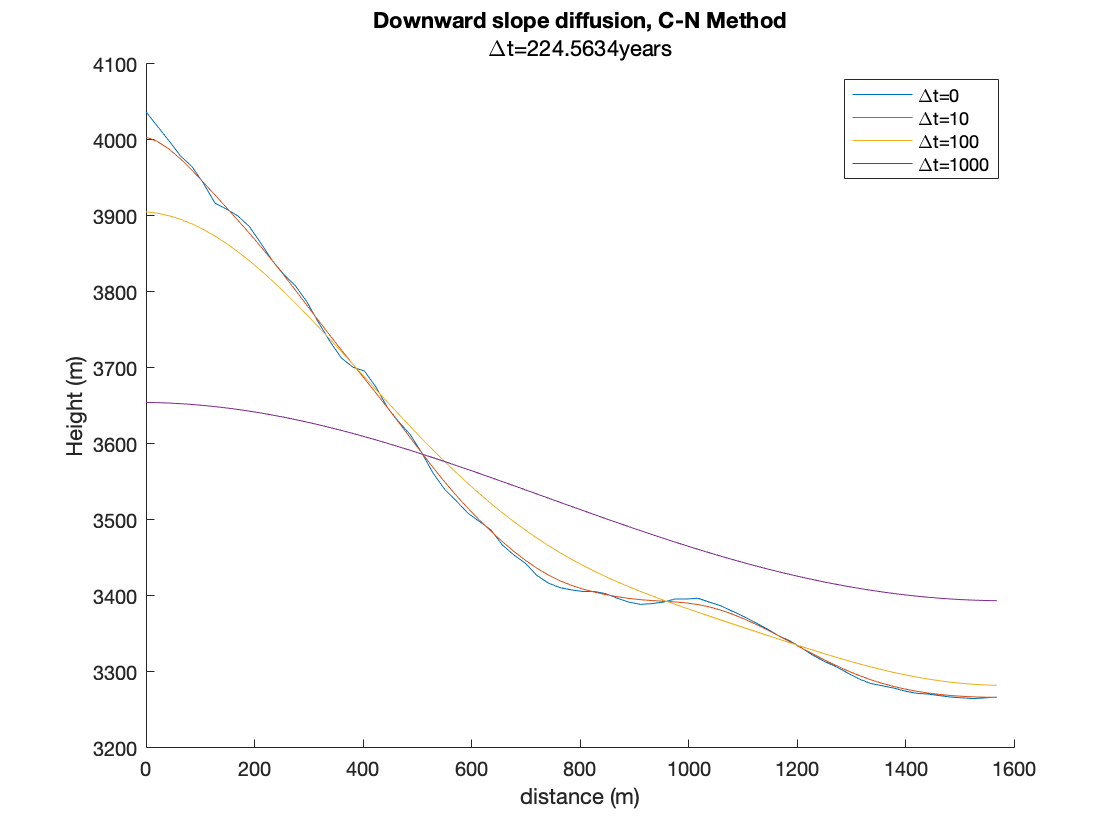

%DownwardSlope (C-N)
load slope1.mat
X=(X-X(end))*40075*(10^3)*cos(lat)/360; %m 
X= fliplr(X);
Z= fliplr(Z);
m=length(Z);
dx=X(2);

Cd=.5;
D=1; %m/yr
dt=Cd*dx^2/D;

n=1000;

Zik2=nan.*ones(length(Z),n);
Zik2(:,1)=Z; 


M1 = sparse(m,m);
for i = 1:m
    for j = 1:m
        if i==j
            M1(i,j) = 1+Cd;
        elseif i-1==j
            M1(i,j) = -.5*Cd;
        elseif i+1==j
            M1(i,j) = -.5*Cd;
        end
    end
end
M1(1,1)=1+Cd;

M2 = sparse(m,m);
for i = 1:m
    for j = 1:m
        if i==j
            M2(i,j) = 1-Cd;
        elseif i-1==j
            M2(i,j) = .5*Cd;
        elseif i+1==j
            M2(i,j) = .5*Cd;
        end
    end
end
M2(1,1)=1;
M2(end,end)=1;

    

Z=Zik2(:,1);
for i=1:(n); 
    Znew=inv(M1)*(M2*Z);
    Zik2(:,i+1)=Znew;
    Z=Znew;
end

figure(4)
hold on
plot(X,Zik2(:,1));
plot(X,Zik2(:,10));
plot(X,Zik2(:,100));
plot(X,Zik2(:,1000));
legend('\Deltat=0','\Deltat=10','\Deltat=100','\Deltat=1000')
title('Downward slope diffusion, C-N Method')
subtitle(['\Deltat=',num2str(dt),'years'])
xlabel('distance (m)')
ylabel('Height (m)')

The Crank-Nicholson method may be more accurate, but the same problem persists. The diffusion occurs on both sides of the profile, so the next attempt uses a transect with a peak in the middle.

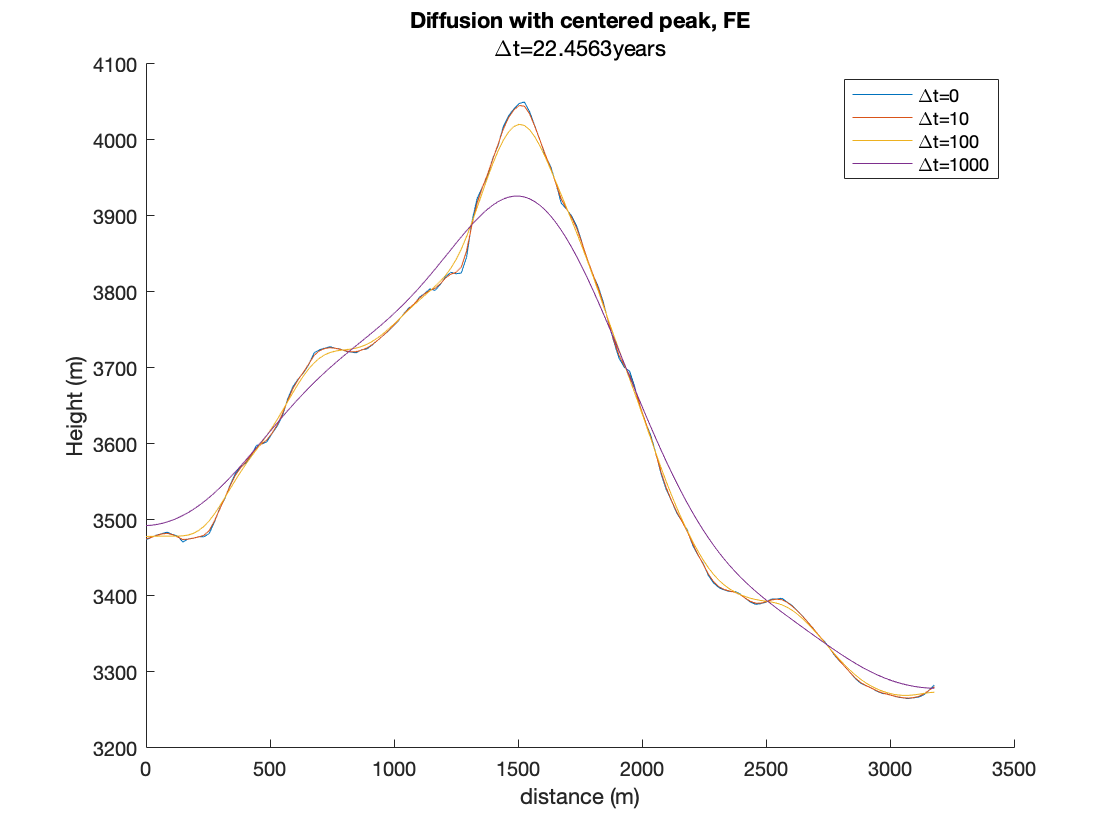

%Centered peak hillslope diffusion
load slope_central_peak.mat 
X=(X-X(end))*40075*(10^3)*cos(lat)/360; %m 
X= fliplr(X);
Z= fliplr(Z);
m=length(Z);
dx=X(2);

Cd=.05;
D=1; % m/yr
dt=Cd*dx^2/D;

n=1000;

Zik=nan.*ones(length(Z),n);
Zik(:,1)=Z; 


M = sparse(m,m);
for i = 1:m
    for j = 1:m
        if i==j
            M(i,j) = 1-2*Cd;
        elseif i-1==j
            M(i,j) = Cd;
        elseif i+1==j
            M(i,j) = Cd;
        end
    end
end
M(1,1)=1-Cd;
M(end,end)=1-Cd;


Z=Zik(:,1);
for i=1:(n); 
    Znew=M*Z;
    Zik(:,i+1)=Znew;
    Z=Znew;
end

figure(5)
hold on
plot(X,Zik(:,1))
plot(X,Zik(:,10))
plot(X,Zik(:,100))
plot(X,Zik(:,1000))
legend('\Deltat=0','\Deltat=10','\Deltat=100','\Deltat=1000')
title('Diffusion with centered peak, FE')
subtitle(['\Deltat=',num2str(dt),'years'])
xlabel('distance (m)')
ylabel('Height (m)')

This appears to be more reaslistic, but perhaps the Forward Euler Method is not producing the best results. Since it is conditionally stable, the unconditionally stable methods are tried next.

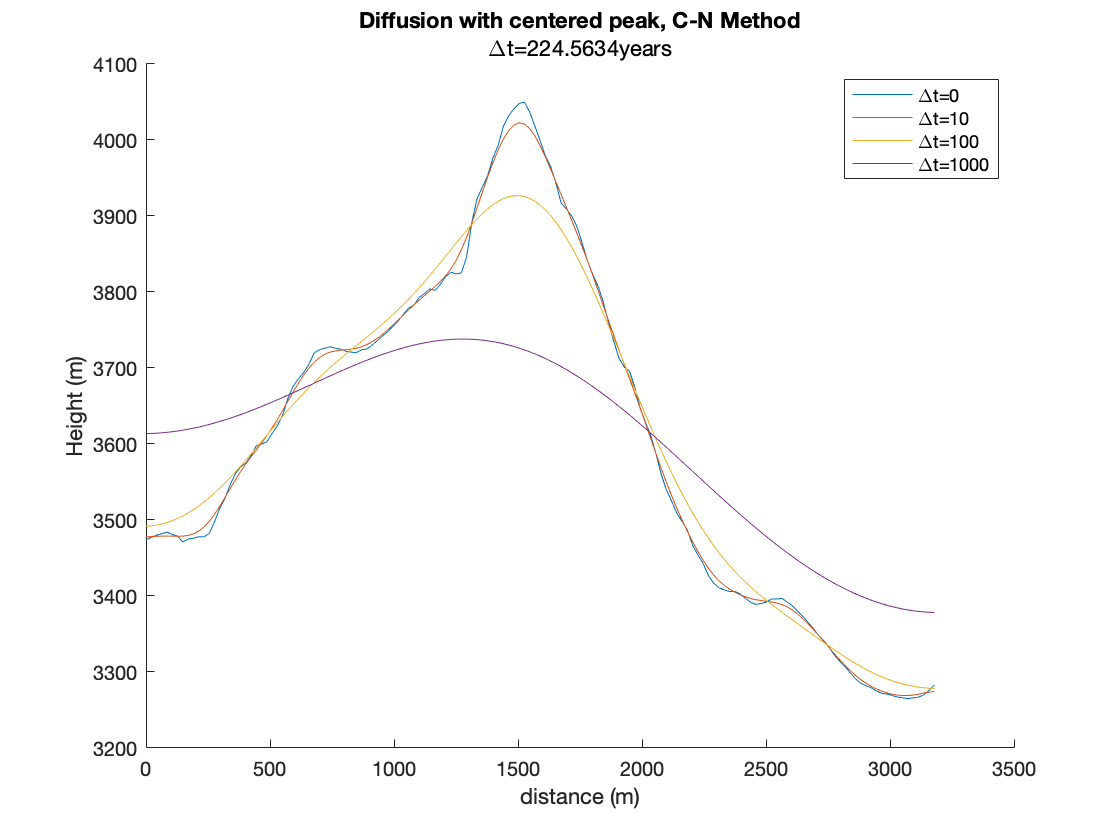

%Centered peak hillslope diffusion (C-N)
load slope_central_peak.mat 
X=(X-X(end))*40075*(10^3)*cos(lat)/360; %m 
X= fliplr(X);
Z= fliplr(Z);
m=length(Z);
dx=X(2);

Cd=.5;
D=1; %m/yr
dt=Cd*dx^2/D;

n=1000;

Zik2=nan.*ones(length(Z),n);
Zik2(:,1)=Z; 


M1 = sparse(m,m);
for i = 1:m
    for j = 1:m
        if i==j
            M1(i,j) = 1+Cd;
        elseif i-1==j
            M1(i,j) = -.5*Cd;
        elseif i+1==j
            M1(i,j) = -.5*Cd;
        end
    end
end
M1(1,1)=1+Cd;

M2 = sparse(m,m);
for i = 1:m
    for j = 1:m
        if i==j
            M2(i,j) = 1-Cd;
        elseif i-1==j
            M2(i,j) = .5*Cd;
        elseif i+1==j
            M2(i,j) = .5*Cd;
        end
    end
end
M2(1,1)=1;
M2(end,end)=1;

    

Z=Zik2(:,1);
for i=1:(n); 
    Znew=inv(M1)*(M2*Z);
    Zik2(:,i+1)=Znew;
    Z=Znew;
end

figure(6)
hold on
plot(X,Zik2(:,1));
plot(X,Zik2(:,10));
plot(X,Zik2(:,100));
plot(X,Zik2(:,1000));
legend('\Deltat=0','\Deltat=10','\Deltat=100','\Deltat=1000')
title('Diffusion with centered peak, C-N Method')
subtitle(['\Deltat=',num2str(dt),'years'])
xlabel('distance (m)')
ylabel('Height (m)')

Crank-Nicholson takes into account more points when calculating the unknown point, so it tends to be more accurate. To see if this is the case here, the Backward Euler is also implemented. It is equally stable, as expected, but it also has very similar results.

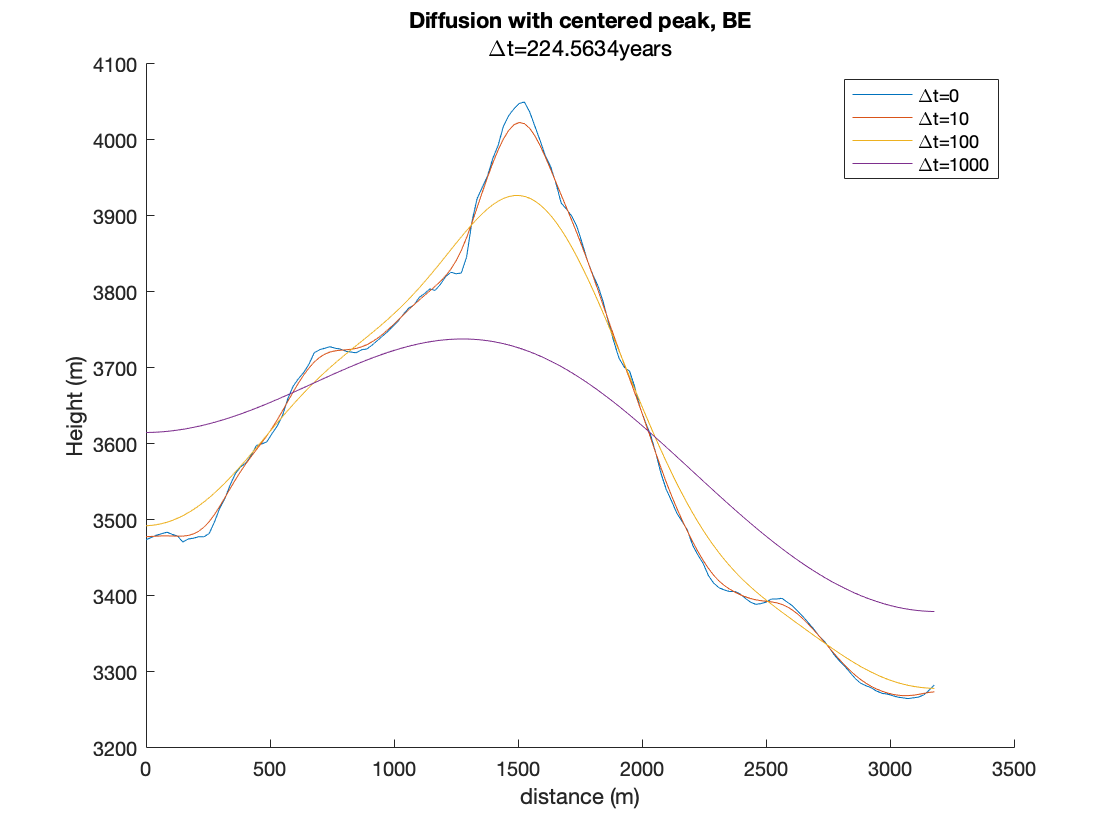

% BE Method
%Centered peak hillslope diffusion
load slope_central_peak.mat 
X=(X-X(end))*40075*(10^3)*cos(lat)/360; %m 
X= fliplr(X);
Z= fliplr(Z);
m=length(Z);
dx=X(2);

Cd=.5;
D=1;
dt=Cd*dx^2/D;

n=1000;

Zik=nan.*ones(length(Z),n);
Zik(:,1)=Z; 


M = sparse(m,m);
for i = 1:m
    for j = 1:m
        if i==j
            M(i,j) = 1+2*Cd;
        elseif i-1==j
            M(i,j) = -Cd;
        elseif i+1==j
            M(i,j) = -Cd;
        end
    end
end
M(1,1)=1+Cd;
M(end,end)=1+Cd;


Z=Zik(:,1);
for i=1:(n); 
    Znew=inv(M)*Z;
    Zik(:,i+1)=Znew;
    Z=Znew;
end

figure(7)
hold on
plot(X,Zik(:,1))
plot(X,Zik(:,10))
plot(X,Zik(:,100))
plot(X,Zik(:,1000))
legend('\Deltat=0','\Deltat=10','\Deltat=100','\Deltat=1000')
title('Diffusion with centered peak, BE')
subtitle(['\Deltat=',num2str(dt),'years'])
xlabel('distance (m)')
ylabel('Height (m)')

Treating the problem like a hillslope diffusion problem yielded more reasonable results, but admittedly strayed further from the original paper by Willgoose because it does not specify the flow of water causing erosion. The figure shows the transect changing from its original to various amounts of timesteps later. These changes are similar to what is expected of erosion. Older mountain ranges such as the Appalachian Mountains have been smoothed and rounded, similar to the smoothing which occurs on the transect pulled from the younger Rocky Mountains. Willgoose's Figure 4 (1994) incorporates diffusive and advective transportation, but it overall shows a similar sloping of the transect.

Changing methods from advection to diffusion made a very big difference as far as the mountain slope acting as one would expect due to detachment-limited transport of sediment. Changing the transect to diffuse in both the positive and negative x directions also made the results more reasonable. In realizing that the diffusion method fits best when there is diffusion in both positive and negative x directions, it was helpful to choose a more appropriate transect. Changing the parameters further also had some effects. For instance, adjusting $C_d$ to make $t$ smaller lowers the erosion effect. This is to be expected. Finally, changing the boundary conditions from a no-flux boundary condition resulted in an unreasonable dip at the edges of the graph.

## Conclusions

These models could be improved in multiple ways. Firstly, the advection model could be improved by correctly applying a spatial divergence operator (*Hillslope processes*) to facilitate downslope. One other solution that was attempted was to interpolate a line from the $\left(x,z\right)$ points. This line or simply the slope between the last two points could be used to adjust the current $z$ value as calculated by advection. This could change the advection's direction at each $x$ in time.

Secondly, the diffusion model could be improved by implementing the rate of tectonic uplift, $U$. Adding $U$would offset some of the downward motion of the peaks, without changing the smoothing effect on the whole mountain. Another possible improvement is a dynamic diffusivity coefficient $D$. In reality, $D$ would not likely be constant, and could be dependent on slope. 

Thirdly, most landscape evolution debate centers around the processes themselves and their parameters (Willgoose 2005). The model would be improved with improved parameters, so optimizing the parameters using a DEM's change over time would be helpful now that DEMs have been around quite a few decades. Willgoose (2005) is confined to testing the models using Monte Carlo simulations, but shorter time-scale data may now be available to test the models. Still, the models shown above indicate that serious change requires hundreds of years, so the true effectiveness of this method may take a while longer.

Beyond timescales, the models discussed by Willgoose (2005,1994) were very informative regarding a process, landscape evolution, about which the students had limited knowledge. For instance, the simple conservation of mass as it is eroded became clearly an important part of the process to be modeled, as the eroded sediment is deposited further down the mountain slope. It also became clear that these complex processes were very difficult to emulate numerically but were equally fascinating to read about along with the many attempts to quantify them.

## References

Caviedes-Voullième, D., Ahmadinia, E., & Hinz, C. (2021). Interactions of Microtopography, Slope and Infiltration Cause Complex Rainfall-Runoff Behavior at the Hillslope Scale for Single Rainfall Events. *Water Resources Research*, *57*(7), e2020WR028127.[ https://doi.org/10.1029/2020WR028127](https://doi.org/10.1029/2020WR028127)

*Hillslope processes—EarthSurface 0.0.1 documentation*. (n.d.). Retrieved December 7, 2021, from[ https://earthsurface.readthedocs.io/en/latest/hillslope.html#modelling-soil-transport](https://earthsurface.readthedocs.io/en/latest/hillslope.html#modelling-soil-transport)

Pelletier, J. (n.d.). *2.3 Fundamental Principles and Techniques of Landscape Evolution Modeling*. 15.

Willgoose, G. (1994). A physical explanation for an observed area-slope-elevation relationship for catchments with declining relief. *Water Resources Research*, *30*(2), 151–159.[ https://doi.org/10.1029/93WR01810](https://doi.org/10.1029/93WR01810)

Willgoose, G. (2005). Mathematical Modeling of Whole Landscape Evolution. *Annual Review of Earth and Planetary Sciences*, *33*(1), 443–459.[ https://doi.org/10.1146/annurev.earth.33.092203.122610](https://doi.org/10.1146/annurev.earth.33.092203.122610)